%% Parameters van de bol
R = 5;      % straal in meters (5 cm)
N = 10;        % resolutie, hoe hoger N hoe meer punten

linspace(0, pi, N)

ans =          0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416


linspace(0, 2*pi, 2*N)

ans =          0    0.3307    0.6614    0.9921    1.3228    1.6535    1.9842    2.3149    2.6456    2.9762    3.3069    3.6376    3.9683    4.2990    4.6297    4.9604    5.2911    5.6218    5.9525    6.2832



%% Maak sferische coördinaten
[theta, phi] = meshgrid(linspace(0, pi, N), linspace(0, 2*pi, 2*N))

theta =          0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435    2.7925    3.1416
         0    0.3491    0.6981    1.0472    1.3963    1.7453    2.0944    2.4435   

phi =          0         0         0         0         0         0         0         0         0         0
    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307
    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614
    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921
    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228
    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535
    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842
    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149
    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456
    2.9762    2.9762    2.9762    2.9762    2.9762    2.9762    2.9762    2.9762    2


%% Converteer naar cartesiaanse coördinaten
X = R * sin(theta) .* cos(phi)

X =          0    1.7101    3.2139    4.3301    4.9240    4.9240    4.3301    3.2139    1.7101    0.0000
         0    1.6174    3.0398    4.0955    4.6572    4.6572    4.0955    3.0398    1.6174    0.0000
         0    1.3495    2.5362    3.4171    3.8858    3.8858    3.4171    2.5362    1.3495    0.0000
         0    0.9353    1.7579    2.3684    2.6932    2.6932    2.3684    1.7579    0.9353    0.0000
         0    0.4198    0.7890    1.0630    1.2088    1.2088    1.0630    0.7890    0.4198    0.0000
         0   -0.1412   -0.2654   -0.3576   -0.4066   -0.4066   -0.3576   -0.2654   -0.1412   -0.0000
         0   -0.6869   -1.2910   -1.7394   -1.9780   -1.9780   -1.7394   -1.2910   -0.6869   -0.0000
         0   -1.1582   -2.1767   -2.9327   -3.3350   -3.3350   -2.9327   -2.1767   -1.1582   -0.0000
         0   -1.5040   -2.8266   -3.8082   -4.3306   -4.3306   -3.8082   -2.8266   -1.5040   -0.0000
         0   -1.6868   -3.1701   -4.2711   -4.8569   -4.8569   -4.2711   -3.1701   -1.6

Y = R * sin(theta) .* sin(phi);
Z = R * cos(theta);

%% Zet alles in een N*3 matrix
sphere_ptcld = [X(:), Y(:), Z(:)];

%% Verwijder eventueel dubbele rijen
sphere_ptcld = unique(sphere_ptcld, 'rows');

%% Stuur naar base workspace (voor gebruik in Simscape)20
assignin('base', 'sphere_ptcld', sphere_ptcld);

figure;
scatter3(sphere_ptcld(:,1), sphere_ptcld(:,2), sphere_ptcld(:,3), 20, 'filled');50

ans = 50

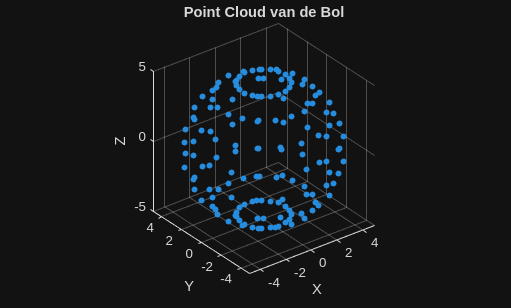

axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Point Cloud van de Bol');
grid on;